# manuscript 3 figures

## Figure 2. Low zoom time-averaged power spectra 

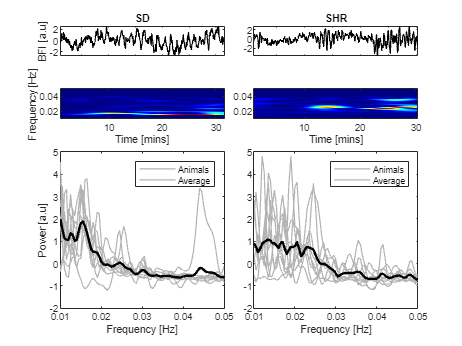

load('lzDataSD.mat')
SD = lzData;
%tmpFiltSD = {SD.animal.tmpFilt}.';
tmpFiltSD = {SD.animal.tmp}.';
foisSD = SD.fois;
load('lzDataSHR.mat')
SHR = lzData;
clearvars lzData
%tmpFiltSHR = {SHR.animal.tmpFilt}.';
tmpFiltSHR = {SHR.animal.tmp}.';
foisSHR = SHR.fois;

figure
t = tiledlayout(5,2);
t.TileSpacing = 'tight';

animalSD = 2;
animalSHR = 1;
% SD: normalized blood flow time series 
ax1 = nexttile(1);
t = SD.animal(animalSD).t;
tsMean = SD.animal(animalSD).tsMean;
plot(t,tsMean,'k','LineWidth',1);
ylabel('BFI [a.u]');
title('SD')
axis tight 
xticklabels(ax1,{})

% SD: scalogram 
ax2 = nexttile(3);
fois = SD.fois;
tmpFilt = SD.animal(animalSD).tmpFilt;
imagesc(t,fois,tmpFilt);
set(gca, 'ydir', 'normal');
colormap jet;
xlabel('Time [mins]');
ylabel('Frequency [Hz]');

% SD: power spectra 
ax3 = nexttile(5,[3 1]);
avgTmp = zeros(9,length(fois));
for i = 1:length(tmpFiltSD)
    meanTmpFilt = mean(cell2mat(tmpFiltSD(i)),2,'omitnan');
    meanTmpFilt = normalize(meanTmpFilt);
    avgTmp(i,:) = meanTmpFilt;
end 
plot(foisSD,avgTmp,'LineWidth',1,'Color',[.7 .7 .7])
hold on 
avgTmp = squeeze(mean(avgTmp,1))';
plot(foisSD,avgTmp,'k','LineWidth',2)
hold off 
legend Animals Average
xlabel('Frequency [Hz]')
ylabel('Power [a.u]')

% SHR: normalized blood flow time series 
ax4 = nexttile(2);
t = SHR.animal(animalSHR).t;
tsMean = SHR.animal(animalSHR).tsMean;
plot(t,tsMean,'k','LineWidth',1)
axis tight
%xlabel('Time [mins]')
title('SHR')
xticklabels(ax4,{})

% SHR: scalogram 
ax5 = nexttile(4);
fois = SHR.fois;
tmpFilt = SHR.animal(animalSHR).tmpFilt;
imagesc(t,fois,tmpFilt);
set(gca, 'ydir', 'normal');
colormap jet;
xlabel('Time [mins]');

% SHR: power spectra 
ax6 = nexttile(6,[3 1]);
avgTmp = zeros(9,length(fois));
for i = 1:length(tmpFiltSHR)
    meanTmpFilt = mean(cell2mat(tmpFiltSHR(i)),2,'omitnan');
    meanTmpFilt = normalize(meanTmpFilt);
    avgTmp(i,:) = meanTmpFilt;
end 
plot(foisSHR,avgTmp,'LineWidth',1,'Color',[.7 .7 .7])
hold on
avgTmp = squeeze(mean(avgTmp,1))';
plot(foisSD,avgTmp,'k','LineWidth',2)
hold off 
legend Animals Average
xlabel('Frequency [Hz]')

## Table 1: collect SD High zoom parameters 

fNames{1} ='Norm1HighBase_reg_segmented.mat'; 
fNames{2} ='Norm2HighBase_reg_segmented.mat'; 
fNames{3} ='Norm3HighBase_reg_segmented.mat'; 
fNames{4} ='Norm4HighBase_reg_segmented.mat'; 
fNames{5} ='Norm5HighBase_reg_segmented.mat'; 
fNames{6} ='Norm6HighBase_reg_segmented.mat'; 
fNames{7} ='Norm7HighBase_reg_segmented.mat'; 
fNames{8} ='Norm9HighBase_reg_segmented.mat'; 
fNames{9} ='Norm10HighBase_reg_segmented.mat';

% get total vessel count for SD 
count = 0; 
for i = 1:length(fNames)
    load(fNames{i});
    count = count + length(result.segmves);
end

% preallocate for SD parameters 
bfi = zeros(count,1); 
sigma = zeros(count,1); 
aucNoisy = zeros(count,1); 
aucPass = zeros(count,1);
SNRauc = zeros(count,1); 
SNRsig = zeros(count,1); 
numPks = zeros(count,1); 
pks = zeros(count,1); 
locs = zeros(count,1); 
w = zeros(count,1); 
p = zeros(count,1); 
animal = categorical(ones(count,1));

% extract SD paramaters 
idx = 1; 
for i = 1:length(fNames)
    load(fNames{i}); 
    vesCount = length(result.segmves);
    bfi(idx:idx+vesCount-1) = [result.segmves.meanBfi].';
    sigma(idx:idx+vesCount-1) = [result.segmves.sigma].';
    aucNoisy(idx:idx+vesCount-1) = [result.segmves.aucNoisy].';
    aucPass(idx:idx+vesCount-1) = [result.segmves.aucPass].';
    SNRauc(idx:idx+vesCount-1) = [result.segmves.SNRauc].';
    SNRsig(idx:idx+vesCount-1) = [result.segmves.SNRsig].';
    numPks(idx:idx+vesCount-1) = [result.segmves.numPks].';
    % extract mmost prominent peak parameters 
    pksDom = zeros(vesCount,1); 
    locsDom =zeros(vesCount,1); 
    wDom = zeros(vesCount,1); 
    pDom = zeros(vesCount,1); 
    for ii = 1:length(result.segmves)
        pksDom(ii) = result.segmves(ii).pks(1); 
        locsDom(ii) = result.segmves(ii).locs(1); 
        wDom(ii) = result.segmves(ii).w(1);
        pDom(ii) = max(result.segmves(ii).p(1));
    end 
    pks(idx:idx+vesCount-1) = pksDom; 
    locs(idx:idx+vesCount-1) = locsDom; 
    w(idx:idx+vesCount-1) = wDom; 
    p(idx:idx+vesCount-1) = pDom;
    % update index number 
    idx = idx + vesCount;
end 
SD = table(animal,bfi,sigma,aucNoisy,aucPass,SNRauc,SNRsig,...
    numPks,pks,locs,w,p);

## Table 1: collect SHR High zoom parameters

fNames{1} ='SHR1HighBase_reg_segmented.mat'; 
fNames{2} ='SHR2HighBase_reg_segmented.mat'; 
fNames{3} ='SHR3HighBase_reg_segmented.mat'; 
fNames{4} ='SHR4HighBase_reg_segmented.mat'; 
fNames{5} ='SHR5HighBase_reg_segmented.mat'; 
fNames{6} ='SHR6HighBase_reg_segmented.mat'; 
fNames{7} ='SHR7HighBase_reg_segmented.mat'; 
fNames{8} ='SHR8HighBase_reg_segmented.mat'; 
fNames{9} ='SHR9HighBase_reg_segmented.mat';

% get total vessel count for S
count = 0; 
for i = 1:length(fNames)
    load(fNames{i});
    count = count + length(result.segmves);
end

% preallocate for SH parameters 
bfi = zeros(count,1); 
sigma = zeros(count,1); 
aucNoisy = zeros(count,1); 
aucPass = zeros(count,1);
SNRauc = zeros(count,1); 
SNRsig = zeros(count,1); 
numPks = zeros(count,1); 
pks = zeros(count,1); 
locs = zeros(count,1); 
w = zeros(count,1); 
p = zeros(count,1); 
animal = categorical(ones(count,1)*2);

% extract SD paramaters 
idx = 1; 
for i = 1:length(fNames)
    load(fNames{i}); 
    vesCount = length(result.segmves);
    bfi(idx:idx+vesCount-1) = [result.segmves.meanBfi].';
    sigma(idx:idx+vesCount-1) = [result.segmves.sigma].';
    aucNoisy(idx:idx+vesCount-1) = [result.segmves.aucNoisy].';
    aucPass(idx:idx+vesCount-1) = [result.segmves.aucPass].';
    SNRauc(idx:idx+vesCount-1) = [result.segmves.SNRauc].';
    SNRsig(idx:idx+vesCount-1) = [result.segmves.SNRsig].';
    numPks(idx:idx+vesCount-1) = [result.segmves.numPks].';
    % extract mmost prominent peak parameters 
    pksDom = zeros(vesCount,1); 
    locsDom =zeros(vesCount,1); 
    wDom = zeros(vesCount,1); 
    pDom = zeros(vesCount,1); 
    for ii = 1:length(result.segmves)
        pksDom(ii) = result.segmves(ii).pks(1); 
        locsDom(ii) = result.segmves(ii).locs(1); 
        wDom(ii) = result.segmves(ii).w(1);
        pDom(ii) = max(result.segmves(ii).p(1));
    end 
    pks(idx:idx+vesCount-1) = pksDom; 
    locs(idx:idx+vesCount-1) = locsDom; 
    w(idx:idx+vesCount-1) = wDom; 
    p(idx:idx+vesCount-1) = pDom;
    % update index number 
    idx = idx + vesCount;
end 
SHR = table(animal,bfi,sigma,aucNoisy,aucPass,SNRauc,SNRsig,...
    numPks,pks,locs,w,p);

save 'hzMetrics.mat' SD SHR

## combine SD and SHR table for plots 

load hzMetrics.mat 
animal = [SD.animal;SHR.animal]; 
bfi =[SD.bfi;SHR.bfi]; 
sigma = [SD.sigma;SHR.sigma]; 
aucNoisy = [SD.aucNoisy;SHR.aucNoisy]; 
aucPass = [SD.aucPass;SHR.aucPass]; 
SNRauc = [SD.SNRauc;SHR.SNRauc]; 
SNRsig = [SD.SNRsig;SHR.SNRsig]; 
numPks = [SD.numPks;SHR.numPks]; 
pks = [SD.pks;SHR.pks]; 
locs = [SD.locs;SHR.locs]; 
w = [SD.w;SHR.w]; 
p = [SD.p;SHR.p]; 
ALL = table(animal,bfi,sigma,aucNoisy,aucPass,SNRauc,SNRsig,... 
numPks,pks,locs,w,p); 
save 'hzMetrics.mat' ALL -append

## wilcoxon ranksum test

load('hzMetrics.mat','SD','SHR')
[pBfi,hBfi,statsBfi] = ranksum(SD.bfi,SHR.bfi)

pBfi = 0.0130

hBfi = logical
   1


statsBfi = struct with fields:
       zval: -2.4832
    ranksum: 80079


%[pSigma,hSigma,statsSigma] = ranksum(SD.sigma,SHR.sigma)
%[pAucNoisy,hAucNoisy,statsAucNoisy] = ranksum(SD.aucNoisy,SHR.aucNoisy)
[pAucPass,hAucPass,statsAucPass] = ranksum(SD.aucPass,SHR.aucPass)

pAucPass = 1.4187e-04

hAucPass = logical
   1


statsAucPass = struct with fields:
       zval: 3.8049
    ranksum: 91299


[pSNRauc,hSNRauc,statsSNRauc] = ranksum(SD.SNRauc,SHR.SNRauc)

pSNRauc = 9.5070e-15

hSNRauc = logical
   1


statsSNRauc = struct with fields:
       zval: 7.7457
    ranksum: 98330


%[pSNRsig,hSNRsig,statsSNRsig] = ranksum(SD.SNRsig,SHR.SNRsig)
%[pNumPks,hNumPks,statsNumPks] = ranksum(SD.numPks,SHR.numPks)
%[pPks,hPks,statsPks] = ranksum(SD.pks,SHR.pks)
[pLocs,hLocs,statsLocs] = ranksum(SD.locs,SHR.locs)

pLocs = 0.0030

hLocs = logical
   1


statsLocs = struct with fields:
       zval: -2.9685
    ranksum: 7.9220e+04


%[pW,hW,statsW] = ranksum(SD.w,SHR.w)
[pP,hP,statsP] = ranksum(SD.p,SHR.p)

pP = 3.6996e-05

hP = logical
   1


statsP = struct with fields:
       zval: 4.1255
    ranksum: 91871


## Box and whisker plots and stat table 

mSD = zeros(6,1);
qSD = zeros(6,2);
mSH = zeros(6,1);
qSH = zeros(6,2);
pVal = zeros(6,1);
zVal = zeros(6,1);
rsVal = zeros(6,1);

figure
tiledlayout(1,5)
nexttile
varSD = rmoutliers(SD.bfi,"quartiles");
varSHR = rmoutliers(SHR.bfi,"quartiles");
x = [varSD;varSHR];
g1 = repmat({'SD'},length(varSD),1);
g2 = repmat({'SHR'},length(varSHR),1);
g = [g1;g2];
boxplot(x,g,'Notch','on','Symbol','','Colors','kk')

H=sigstar([1,2],pBfi);
title('BFI')
ylabel('BFI [a.u]')
pbaspect([1 2 1])
mSD(1) = median(varSD);
qSD(1,:) = quantile(varSD,[0.25 0.75]);
mSH(1) = median(varSHR);
qSH(1,:) = quantile(varSHR,[0.25 0.75]);
pVal(1) = pBfi;
zVal(1) = statsP.zval;
rsVal(1) = statsP.ranksum;


nexttile
varSD = rmoutliers(SD.aucPass,"quartiles");
varSHR = rmoutliers(SHR.aucPass,"quartiles");
x = [varSD;varSHR];
g1 = repmat({'SD'},length(varSD),1);
g2 = repmat({'SHR'},length(varSHR),1);
g = [g1;g2];
boxplot(x,g,'Notch','on','Symbol','','Colors','kk')

H=sigstar([1,2],pAucPass);
title('AUC')
ylabel('AUC [a.u]')
pbaspect([1 2 1])
mSD(2) = median(varSD);
qSD(2,:) = quantile(varSD,[0.25 0.75]);
mSH(2) = median(varSHR);
qSH(2,:) = quantile(varSHR,[0.25 0.75]);
pVal(2) = pAucPass;
zVal(2) = statsAucPass.zval;
rsVal(2) = statsAucPass.ranksum;

nexttile
varSD = rmoutliers(SD.SNRauc,"quartiles");
varSHR = rmoutliers(SHR.SNRauc,"quartiles");
x = [varSD;varSHR];
g1 = repmat({'SD'},length(varSD),1);
g2 = repmat({'SHR'},length(varSHR),1);
g = [g1;g2];
boxplot(x,g,'Notch','on','Symbol','','Colors','kk')

H=sigstar([1,2],pSNRauc);
title('SNR')
ylabel('SNR [a.u]')
pbaspect([1 2 1])
mSD(3) = median(varSD);
qSD(3,:) = quantile(varSD,[0.25 0.75]);
mSH(3) = median(varSHR);
qSH(3,:) = quantile(varSHR,[0.25 0.75]);
pVal(3) = pSNRauc;
zVal(3) = statsSNRauc.zval;
rsVal(3) = statsSNRauc.ranksum;

nexttile
varSD = rmoutliers(SD.locs,"quartiles");
varSHR = rmoutliers(SHR.locs,"quartiles");
x = [varSD;varSHR];
g1 = repmat({'SD'},length(varSD),1);
g2 = repmat({'SHR'},length(varSHR),1);
g = [g1;g2];
boxplot(x,g,'Notch','on','Symbol','','Colors','kk')

H=sigstar([1,2],pLocs);
title('Frequency')
ylabel('Frequency [Hz]')
pbaspect([1 2 1])
mSD(4) = median(varSD);
qSD(4,:) = quantile(varSD,[0.25 0.75]);
mSH(4) = median(varSHR);
qSH(4,:) = quantile(varSHR,[0.25 0.75]);
pVal(4) = pLocs;
zVal(4) = statsLocs.zval;
rsVal(4) = statsLocs.ranksum;

nexttile
varSD = rmoutliers(SD.p,"quartiles");
varSHR = rmoutliers(SHR.p,"quartiles");
x = [varSD;varSHR];
g1 = repmat({'SD'},length(varSD),1);
g2 = repmat({'SHR'},length(varSHR),1);
g = [g1;g2];
boxplot(x,g,'Notch','on','Symbol','','Colors','kk')

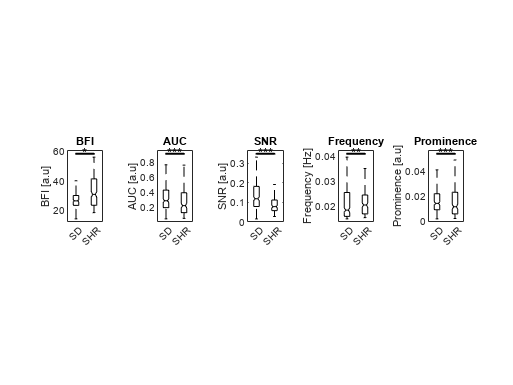

H=sigstar([1,2],pP);
title('Prominence')
ylabel('Prominence [a.u]')
pbaspect([1 2 1])

mSD(5) = median(varSD);
qSD(5,:) = quantile(varSD,[0.25 0.75]);
mSH(5) = median(varSHR);
qSH(5,:) = quantile(varSHR,[0.25 0.75]);
pVal(5) = pP;
zVal(5) = statsP.zval;
rsVal(5) = statsP.ranksum;

statT = table(mSD,qSD,mSH,qSH,pVal,zVal,rsVal)

statT = 6×7 table
      mSD                qSD                mSH                qSH                 pVal        zVal      rsVal
    ________    ______________________    ________    ______________________    __________    _______    _____

       26.25       23.212       29.927      30.671        23.28        41.22      0.013019     4.1255    91871
     0.28318      0.19318      0.42362     0.21871      0.12656      0.38875    0.00014187     3.8049    91299
     0.11806     0.078589      0.18196     0.07816     0.057753      0.11162     9.507e-15     7.7457    98330
      0.0185        0.016       0.0255      0.0205        0.017       0.0245     0.0029923    -2.9685    79220
    0.014187    0.0091661     0.021797    0.011514    0.0058985      0.02296 

## Figure 3: HZ BFI map

load('normBaseThreshImg.mat')
load('Norm1HighBase_reg_segmented.mat')
mask = result.maskId; 
mask(mask ~= 2) = 0;
mask = logical(mask);
figure
% SD: HZ image 
tile = tiledlayout(2,2);
tile.TileSpacing = 'compact';
tile.Padding = 'compact';
ax1 = nexttile(1);
imagesc(img);
clim([prctile(img,5,'all'),prctile(img,99,'all')])
hold on 
visboundaries(mask,'Color','black','LineWidth',1)
hold off 
ax1.XTickLabel = [];
ax1.YTickLabel = [];
colormap(ax1,"hot")
title('SD')
sizePix=1.2; %in microns 
barLen= 200; %desired length in microns 
pixLen= barLen/sizePix; % legnth in pixels 
x = 950;
y= 1100;
hold on 
plot([x; x+pixLen],[y; y],'-w', 'LineWidth', 4)
hold off 

% SD: vessel blood flow 
nexttile(3);
duration = 300; 
t = linspace(1,duration/60,duration);
ts = normalize(result.segmves(6).tsClean(1:duration));
plot(t,ts,'k')
pbaspect([3 1 1]) 
xlabel("Time, [mins]")

% SHR: HZ image
load('shrBaseThreshImg.mat')
load('SHR1HighBase_reg_segmented.mat')
mask = result.maskId; 
mask(mask ~= 6) = 0;
mask = logical(mask);
img = baseThreshImg;
ax2 = nexttile(2);
imagesc(img);
clim([prctile(img,5,'all'),prctile(img,99,'all')])
hold on 
visboundaries(mask,'Color','black','LineWidth',1)
hold off 
ax2.XTickLabel = [];
ax2.YTickLabel = [];
title('SHR')
colormap(ax2,"hot")
sizePix=1.2; %in microns 
barLen= 200; %desired length in microns 
pixLen= barLen/sizePix; % legnth in pixels 
x = 950;
y= 1100;
hold on 
plot([x; x+pixLen],[y; y],'-w', 'LineWidth', 4)
hold off 
colorbar(ax2,"eastoutside","Ticks",[])


nexttile(4);
duration = 300; 
t = linspace(1,duration/60,duration);
ts = normalize(result.segmves(6).tsClean(1:duration));
plot(t,ts,'k')
pbaspect([3 1 1])
axis tight
xlabel("Time, [mins]")



## Figure 4: carpet plots SD vs SHR 

load('Norm2HighBase_reg_segmented.mat');
bfi = cell2mat({result.segmves.tsPass}.');
tmp = [result.segmves.tmpNoisy]';
t = linspace(0,size(bfi,2)/60,size(bfi,2));
fois = result.fois;
range = (fois>0.015 & fois<0.04);
fois = fois(range);
tmpNew = zeros(size(tmp,1),sum(range));
for i = 1:size(tmp,1)
    tmpi = tmp(i,:);
    tmpNew(i,:) = tmpi(range);
end 
tmp = tmpNew;

% SD: BFI carpet plot
f = figure;
tiles = tiledlayout(2,2,'TileSpacing','tight');
ax1 = nexttile(1);
imagesc(bfi,'XData',t)
set(gca, 'ydir', 'normal');
clim([prctile(bfi,5,'all') prctile(bfi,99,'all')])
colormap(ax1,"parula")
axis tight
pbaspect([1.5 1 1])
title('SD')
xlabel('Time [Mins]');
ylabel('vessels');

% SD: Frq carpet plot
ax3 = nexttile(3);
% surf(tmp,'XData',result.fois,'EdgeColor','interp','FaceColor','interp')
% view(2)
imagesc(tmp,'XData',fois);
clim([prctile(tmp,5,'all') prctile(tmp,99,'all')])
colormap(ax3,"jet")
axis tight
pbaspect([1.5 1 1])
set(gca, 'ydir', 'normal');
xlabel('Frequency [Hz]');
ylabel('Vessels');

load('SHR2HighBase_reg_segmented.mat');
bfi = cell2mat({result.segmves.tsPass}.');
tmp = [result.segmves.tmpNoisy]';
t = linspace(0,size(bfi,2)/60,size(bfi,2));
fois = result.fois;
range = (fois>0.015 & fois<0.04);
fois = fois(range);
tmpNew = zeros(size(tmp,1),sum(range));
for i = 1:size(tmp,1)
    tmpi = tmp(i,:);
    tmpNew(i,:) = tmpi(range);
end 
tmp = tmpNew;

% SHR: BFI carpet plot
ax2 = nexttile(2);
% surf(bfi,'XData',t,'EdgeColor','interp','FaceColor','interp')
% view(2)
imagesc(bfi,'XData',t)
set(gca, 'ydir', 'normal');
clim([prctile(bfi,5,'all') prctile(bfi,99,'all')])
colormap(ax2,"parula")
c1 = colorbar;
c1.XTickLabel = [];
axis tight
pbaspect([1.5 1 1])
title('SHR')
xlabel('Time [Mins]');

% SHR: Frq carpet plot
ax4 = nexttile(4);
% surf(tmp,'XData',result.fois,'EdgeColor','interp','FaceColor','interp')
% view(2)
imagesc(tmp,'XData',fois);
clim([prctile(tmp,5,'all') prctile(tmp,99,'all')])
colormap(ax4,"jet")
c2 = colorbar;
c2.XTickLabel = [];
axis tight
pbaspect([1.5 1 1])
set(gca, 'ydir', 'normal');
xlabel('Frequency [Hz]');
c2 = colorbar;
c2.XTickLabel = [];
c2.Position = [0.9240  0.1427 0.0286 0.3154];

% create inset 
MagInset(tiles, ax1, [5 10 2.5 7.5], [15 30 15 27], {'NW','NW';'SE','SE'})
MagInset(tiles, ax2, [5 10 2.5 6.5], [15 30 13 23], {'NW','NW';'SE','SE'})


## SD control/exenatide metrics 

fNames{1} ='Norm1HighBase_reg_segmented.mat'; 
fNames{2} ='Norm2HighBase_reg_segmented.mat'; 
fNames{3} ='Norm3HighBase_reg_segmented.mat'; 
fNames{4} ='Norm4HighBase_reg_segmented.mat'; 
fNames{5} ='Norm5HighBase_reg_segmented.mat'; 
fNames{6} ='Norm6HighBase_reg_segmented.mat'; 
fNames{7} ='Norm7HighBase_reg_segmented.mat'; 
fNames{8} ='Norm9HighBase_reg_segmented.mat'; 
fNames{9} ='Norm10HighBase_reg_segmented.mat';

% get total vessel count for SD 
count = 0; 
for i = 1:length(fNames)
    load(fNames{i}); 
    count = count + length(result.segmves);
end

Error using load
'Norm1HighBase_reg_segmented.mat' is not found in the current folder or on the MATLAB path, but exists in:
    H:\segmentedSD_SHR

Change the MATLAB current folder or add its folder to the MATLAB path.


% preallocate for SD parameters 
bfi = zeros(count,1);
sigma = zeros(count,1); 
aucNoisy = zeros(count,1); 
aucPass = zeros(count,1);
SNRauc = zeros(count,1); 
SNRsig = zeros(count,1); 
numPks = zeros(count,1); 
pks = zeros(count,1); 
locs = zeros(count,1); 
w = zeros(count,1); 
p = zeros(count,1); 
condition = categorical(ones(count,1));
animal = zeros(count,1); 

% extract SD paramaters 
idx = 1; 
for i = 1:length(fNames)
    load(fNames{i}); 
    vesCount = length(result.segmves);
    animal(idx:idx+vesCount-1) = ones(vesCount,1)*i;
    bfi(idx:idx+vesCount-1) = [result.segmves.meanBfi].';
    sigma(idx:idx+vesCount-1) = [result.segmves.sigma].';
    aucNoisy(idx:idx+vesCount-1) = [result.segmves.aucNoisy].';
    aucPass(idx:idx+vesCount-1) = [result.segmves.aucPass].';
    SNRauc(idx:idx+vesCount-1) = [result.segmves.SNRauc].';
    SNRsig(idx:idx+vesCount-1) = [result.segmves.SNRsig].';
    numPks(idx:idx+vesCount-1) = [result.segmves.numPks].'; 
    % extract most prominent peak parameters 
    pksDom = zeros(vesCount,1); 
    locsDom =zeros(vesCount,1); 
    wDom = zeros(vesCount,1); 
    pDom = zeros(vesCount,1); 
    for ii = 1:length(result.segmves)
        pksDom(ii) = result.segmves(ii).pks(1); 
        locsDom(ii) = result.segmves(ii).locs(1); 
        wDom(ii) = result.segmves(ii).w(1);
        pDom(ii) = result.segmves(ii).p(1);
    end 
    pks(idx:idx+vesCount-1) = pksDom; 
    locs(idx:idx+vesCount-1) = locsDom; 
    w(idx:idx+vesCount-1) = wDom; 
    p(idx:idx+vesCount-1) = pDom;
    % update index number 
    idx = idx + vesCount;
end 
control = table(condition,animal,bfi,sigma,aucNoisy,aucPass,SNRauc,SNRsig,...
    numPks,pks,locs,w,p);

fNames{1} = 'Norm1HighPost_reg_segmented.mat'; 
fNames{2} ='Norm2HighPost_reg_segmented.mat'; 
fNames{3} ='Norm3HighPost_reg_segmented.mat'; 
fNames{4} ='Norm4HighPost_reg_segmented.mat'; 
fNames{5} ='Norm5HighPost_reg_segmented.mat'; 
fNames{6} ='Norm6HighPost_reg_segmented.mat'; 
fNames{7} ='Norm7HighPost_reg_segmented.mat'; 
fNames{8} ='Norm9HighPost_reg_segmented.mat'; 
fNames{9} ='Norm10HighPost_reg_segmented.mat';

% get total vessel count for SD 
count = 0; 
for i = 1:length(fNames)
    load(fNames{i}); 
    count = count + length(result.segmves);
end

% preallocate for SD parameters 
bfi = zeros(count,1); 
sigma =zeros(count,1); 
aucNoisy = zeros(count,1); 
aucPass = zeros(count,1);
SNRauc = zeros(count,1); 
SNRsig = zeros(count,1); 
numPks = zeros(count,1); 
pks = zeros(count,1); 
locs = zeros(count,1); 
w = zeros(count,1); 
p = zeros(count,1); 
condition = categorical(ones(count,1)*2);
animal = zeros(count,1); 

% extract SD paramaters 
idx = 1; 
for i = 1:length(fNames)
    load(fNames{i}); 
    vesCount = length(result.segmves);
    animal(idx:idx+vesCount-1) = ones(vesCount,1)*i;
    bfi(idx:idx+vesCount-1) = [result.segmves.meanBfi].';
    sigma(idx:idx+vesCount-1) = [result.segmves.sigma].';
    aucNoisy(idx:idx+vesCount-1) = [result.segmves.aucNoisy].';
    aucPass(idx:idx+vesCount-1) = [result.segmves.aucPass].';
    SNRauc(idx:idx+vesCount-1) = [result.segmves.SNRauc].';
    SNRsig(idx:idx+vesCount-1) = [result.segmves.SNRsig].';
    numPks(idx:idx+vesCount-1) = [result.segmves.numPks].'; 
    % extractmost prominent peak parameters 
    pksDom = zeros(vesCount,1); 
    locsDom =zeros(vesCount,1);
    wDom = zeros(vesCount,1); 
    pDom =zeros(vesCount,1); 
    for ii = 1:length(result.segmves)
        pksDom(ii) = result.segmves(ii).pks(1); 
        locsDom(ii) = result.segmves(ii).locs(1); 
        wDom(ii) = result.segmves(ii).w(1);
        pDom(ii) = result.segmves(ii).p(1);
    end 
    pks(idx:idx+vesCount-1) = pksDom; 
    locs(idx:idx+vesCount-1) = locsDom; 
    w(idx:idx+vesCount-1) = wDom; 
    p(idx:idx+vesCount-1) = pDom;
    % update index number 
    idx = idx + vesCount;
end 
exenatide = table(condition,animal,bfi,sigma,aucNoisy,aucPass,SNRauc,SNRsig,...
    numPks,pks,locs,w,p);

save 'sdMetrics.mat' control exenatide

load sdMetrics.mat 
condition = [control.condition;exenatide.condition]; 
animal = [control.animal;exenatide.animal]
bfi =[control.bfi;exenatide.bfi]; 
sigma = [control.sigma;exenatide.sigma];
aucNoisy = [control.aucNoisy;exenatide.aucNoisy]; 
aucPass =[control.aucPass;exenatide.aucPass]; 
SNRauc =[control.SNRauc;exenatide.SNRauc]; 
SNRsig =[control.SNRsig;exenatide.SNRsig]; 
numPks =[control.numPks;exenatide.numPks]; 
pks = [control.pks;exenatide.pks];
locs = [control.locs;exenatide.locs]; 
w = [control.w;exenatide.w]; 
p =[control.p;exenatide.p];


ALL = table(condition,animal,bfi,sigma,aucNoisy,aucPass,SNRauc,SNRsig,...
    numPks,pks,locs,w,p);
save 'sdMetrics.mat' ALL -append

## SD: wilcoxon ranksum test and box plots 

load('sdMetrics.mat','control','exenatide')
[pBfi,hBfi,statBfi] = signrank(control.bfi,exenatide.bfi)
[pSigma,hSigma,statSigma] = signrank(control.sigma,exenatide.sigma)
[pAucNoisy,hAucNoisy] = signrank(control.aucNoisy,exenatide.aucNoisy)
[pAucPass,hAucPass,statAucPass] = signrank(control.aucPass,exenatide.aucPass)
[pSNRauc,hSNRauc,statSNRauc] = signrank(control.SNRauc,exenatide.SNRauc)
[pSNRsig,hSNRsig] = signrank(control.SNRsig,exenatide.SNRsig)
[pNumPks,hNumPks] = signrank(control.numPks,exenatide.numPks)
[pPks,hPks] = signrank(control.pks,exenatide.pks)
[pLocs,hLocs,statLocs] = signrank(control.locs,exenatide.locs)
[pW,hW] = signrank(control.w,exenatide.w)
[pP,hP,statP] = signrank(control.p,exenatide.p)

## SD: Box plots and stat table 

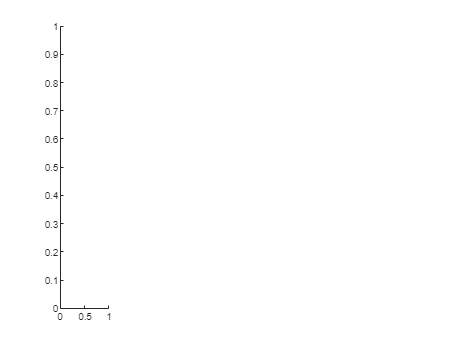

mBase = zeros(6,1);
qBase = zeros(6,2);
mPost = zeros(6,1);
qPost = zeros(6,2);
pVal = zeros(6,1);
zVal = zeros(6,1);
srVal = zeros(6,1);

figure
t = tiledlayout(1,6);
nexttile

varControl = rmoutliers(control.bfi,"quartiles");

Unable to resolve the name 'control.bfi'.

varExenatide = rmoutliers(exenatide.bfi,"quartiles");
x = [varControl;varExenatide];
g1 = repmat({'Control'},length(varControl),1);
g2 = repmat({'Exenatide'},length(varExenatide),1);
g = [g1;g2];
boxplot(x,g,'Notch','on','Symbol','','Colors','kr')
H=sigstar([1,2],pBfi);
title('BFI')
ylabel('BFI [a.u]')
pbaspect([1 2 1])
mBase(1) = median(varControl);
qBase(1,:) = quantile(varControl,[0.25 0.75]);
mPost(1) = median(varExenatide);
qPost(1,:) = quantile(varExenatide,[0.25 0.75]);
pVal(1) = pBfi;
zVal(1) = statBfi.zval;
srVal(1) = statBfi.signedrank;

nexttile
varControl = rmoutliers(control.sigma,"quartiles");
varExenatide = rmoutliers(exenatide.sigma,"quartiles");
x = [varControl;varExenatide];
g1 = repmat({'Control'},length(varControl),1);
g2 = repmat({'Exenatide'},length(varExenatide),1);
g = [g1;g2];
boxplot(x,g,'Notch','on','Symbol','','Colors','kr')
H=sigstar([1,2],pSigma);
title('Sigma')
ylabel('Sigma [a.u]')
pbaspect([1 2 1])
mBase(2) = median(varControl);
qBase(2,:) = quantile(varControl,[0.25 0.75]);
mPost(2) = median(varExenatide);
qPost(2,:) = quantile(varExenatide,[0.25 0.75]);
pVal(2) = pSigma;
zVal(2) = statSigma.zval;
srVal(2) = statSigma.signedrank;

nexttile
varControl = rmoutliers(control.aucPass,"quartiles");
varExenatide = rmoutliers(exenatide.aucPass,"quartiles");
x = [varControl;varExenatide];
g1 = repmat({'Control'},length(varControl),1);
g2 = repmat({'Exenatide'},length(varExenatide),1);
g = [g1;g2];
boxplot(x,g,'Notch','on','Symbol','','Colors','kr')
H=sigstar([1,2],pAucPass);
title('AUC')
ylabel('AUC [a.u]')
pbaspect([1 2 1])
mBase(3) = median(varControl);
qBase(3,:) = quantile(varControl,[0.25 0.75]);
mPost(3) = median(varExenatide);
qPost(3,:) = quantile(varExenatide,[0.25 0.75]);
pVal(3) = pAucPass;
zVal(3) = statAucPass.zval;
srVal(3) = statAucPass.signedrank;


nexttile
varControl = rmoutliers(control.SNRauc,"quartiles");
varExenatide = rmoutliers(exenatide.SNRauc,"quartiles");
x = [varControl;varExenatide];
g1 = repmat({'Control'},length(varControl),1);
g2 = repmat({'Exenatide'},length(varExenatide),1);
g = [g1;g2];
boxplot(x,g,'Notch','on','Symbol','','Colors','kr')
H=sigstar([1,2],pSNRauc);
title('SNR')
ylabel('SNR [a.u]')
pbaspect([1 2 1])
mBase(4) = median(varControl);
qBase(4,:) = quantile(varControl,[0.25 0.75]);
mPost(4) = median(varExenatide);
qPost(4,:) = quantile(varExenatide,[0.25 0.75]);
pVal(4) = pSNRauc;
zVal(4) = statSNRauc.zval;
srVal(4) = statSNRauc.signedrank;

nexttile
varControl = rmoutliers(control.locs,"quartiles");
varExenatide = rmoutliers(exenatide.locs,"quartiles");
x = [varControl;varExenatide];
g1 = repmat({'Control'},length(varControl),1);
g2 = repmat({'Exenatide'},length(varExenatide),1);
g = [g1;g2];
boxplot(x,g,'Notch','on','Symbol','','Colors','kr')
H=sigstar([1,2],pLocs);
title('Frequency')
ylabel('Frequency [Hz]')
pbaspect([1 2 1])
mBase(5) = median(varControl);
qBase(5,:) = quantile(varControl,[0.25 0.75]);
mPost(5) = median(varExenatide);
qPost(5,:) = quantile(varExenatide,[0.25 0.75]);
pVal(5) = pLocs;
zVal(5) = statLocs.zval;
srVal(5) = statLocs.signedrank;

nexttile
varControl = rmoutliers(control.p,"quartiles");
varExenatide = rmoutliers(exenatide.p,"quartiles");
x = [varControl;varExenatide];
g1 = repmat({'Control'},length(varControl),1);
g2 = repmat({'Exenatide'},length(varExenatide),1);
g = [g1;g2];
boxplot(x,g,'Notch','on','Symbol','','Colors','kr')
H=sigstar([1,2],pP);
title('Prominence')
ylabel('Prominence [a.u]')
pbaspect([1 2 1])
mBase(6) = median(varControl);
qBase(6,:) = quantile(varControl,[0.25 0.75]);
mPost(6) = median(varExenatide);
qPost(6,:) = quantile(varExenatide,[0.25 0.75]);
pVal(6) = pP;
zVal(6) = statP.zval;
srVal(6) = statP.signedrank;

t.TileSpacing = 'compact';
t.Padding = 'compact';

statT = table(mBase,qBase,mPost,qPost,pVal,zVal,srVal)

## SHR control/exenatide metrics 

fNames{1} ='SHR1HighBase_reg_segmented.mat'; 
fNames{2} ='SHR2HighBase_reg_segmented.mat'; 
fNames{3} ='SHR3HighBase_reg_segmented.mat'; 
fNames{4} ='SHR4HighBase_reg_segmented.mat'; 
fNames{5} ='SHR5HighBase_reg_segmented.mat'; 
fNames{6} ='SHR6HighBase_reg_segmented.mat'; 
fNames{7} ='SHR7HighBase_reg_segmented.mat'; 
fNames{8} ='SHR8HighBase_reg_segmented.mat'; 
fNames{9} ='SHR9HighBase_reg_segmented.mat';

% get total vessel count for SHR 
count = 0; 
for i = 1:length(fNames)
    load(fNames{i}); 
    count = count + length(result.segmves);
end

% preallocate for SHR parameters 
bfi = zeros(count,1);
sigma = zeros(count,1); 
aucNoisy = zeros(count,1); 
aucPass = zeros(count,1);
SNRauc = zeros(count,1); 
SNRsig = zeros(count,1); 
numPks = zeros(count,1); 
pks = zeros(count,1); 
locs = zeros(count,1); 
w = zeros(count,1); 
p = zeros(count,1); 
condition = categorical(ones(count,1));
animal = zeros(count,1);

% extract SHR paramaters 
idx = 1; 
for i = 1:length(fNames)
    load(fNames{i}); 
    vesCount = length(result.segmves);
    animal(idx:idx+vesCount-1) = ones(vesCount,1)*i;
    bfi(idx:idx+vesCount-1) = [result.segmves.meanBfi].';
    sigma(idx:idx+vesCount-1) = [result.segmves.sigma].';
    aucNoisy(idx:idx+vesCount-1) = [result.segmves.aucNoisy].';
    aucPass(idx:idx+vesCount-1) = [result.segmves.aucPass].';
    SNRauc(idx:idx+vesCount-1) = [result.segmves.SNRauc].';
    SNRsig(idx:idx+vesCount-1) = [result.segmves.SNRsig].';
    numPks(idx:idx+vesCount-1) = [result.segmves.numPks].'; 
    % extract most prominent peak parameters 
    pksDom = zeros(vesCount,1); 
    locsDom =zeros(vesCount,1); 
    wDom = zeros(vesCount,1); 
    pDom = zeros(vesCount,1); 
    for ii = 1:length(result.segmves)
        pksDom(ii) = result.segmves(ii).pks(1); 
        locsDom(ii) = result.segmves(ii).locs(1); 
        wDom(ii) = result.segmves(ii).w(1);
        pDom(ii) = result.segmves(ii).p(1);
    end 
    pks(idx:idx+vesCount-1) = pksDom; 
    locs(idx:idx+vesCount-1) = locsDom; 
    w(idx:idx+vesCount-1) = wDom; 
    p(idx:idx+vesCount-1) = pDom;
    % update index number 
    idx = idx + vesCount;
end 
control = table(condition,animal,bfi,sigma,aucNoisy,aucPass,SNRauc,SNRsig,...
    numPks,pks,locs,w,p);

fNames{1} = 'SHR1HighPost_reg_segmented.mat'; 
fNames{2} ='SHR2HighPost_reg_segmented.mat'; 
fNames{3} ='SHR3HighPost_reg_segmented.mat'; 
fNames{4} ='SHR4HighPost_reg_segmented.mat'; 
fNames{5} ='SHR5HighPost_reg_segmented.mat'; 
fNames{6} ='SHR6HighPost_reg_segmented.mat'; 
fNames{7} ='SHR7HighPost_reg_segmented.mat'; 
fNames{8} ='SHR8HighPost_reg_segmented.mat'; 
fNames{9} ='SHR9HighPost_reg_segmented.mat';

% get total vessel count for SHR 
count = 0; 
for i = 1:length(fNames)
    load(fNames{i}); 
    count = count + length(result.segmves);
end

% preallocate for SHR parameters 
bfi = zeros(count,1); 
sigma =zeros(count,1); 
aucNoisy = zeros(count,1); 
aucPass = zeros(count,1);
SNRauc = zeros(count,1); 
SNRsig = zeros(count,1); 
numPks = zeros(count,1); 
pks = zeros(count,1); 
locs = zeros(count,1); 
w = zeros(count,1); 
p = zeros(count,1); 
condition = categorical(ones(count,1)*2);
animal = zeros(count,1); 

% extract SHR paramaters 
idx = 1; 
for i = 1:length(fNames)
    load(fNames{i}); 
    vesCount = length(result.segmves);
    animal(idx:idx+vesCount-1) = ones(vesCount,1)*i;
    bfi(idx:idx+vesCount-1) = [result.segmves.meanBfi].';
    sigma(idx:idx+vesCount-1) = [result.segmves.sigma].';
    aucNoisy(idx:idx+vesCount-1) = [result.segmves.aucNoisy].';
    aucPass(idx:idx+vesCount-1) = [result.segmves.aucPass].';
    SNRauc(idx:idx+vesCount-1) = [result.segmves.SNRauc].';
    SNRsig(idx:idx+vesCount-1) = [result.segmves.SNRsig].';
    numPks(idx:idx+vesCount-1) = [result.segmves.numPks].'; 
    % extract most prominent peak parameters 
    pksDom = zeros(vesCount,1); 
    locsDom =zeros(vesCount,1);
    wDom = zeros(vesCount,1); 
    pDom =zeros(vesCount,1); 
    for ii = 1:length(result.segmves)
        pksDom(ii) = result.segmves(ii).pks(1); 
        locsDom(ii) = result.segmves(ii).locs(1); 
        wDom(ii) = result.segmves(ii).w(1);
        pDom(ii) = result.segmves(ii).p(1);
    end 
    pks(idx:idx+vesCount-1) = pksDom; 
    locs(idx:idx+vesCount-1) = locsDom; 
    w(idx:idx+vesCount-1) = wDom; 
    p(idx:idx+vesCount-1) = pDom;
    % update index number 
    idx = idx + vesCount;
end 
exenatide = table(condition,animal,bfi,sigma,aucNoisy,aucPass,SNRauc,SNRsig,...
    numPks,pks,locs,w,p);

save 'shrMetrics.mat' control exenatide

load shrMetrics.mat 
condition = [control.condition;exenatide.condition]; 
animal = [control.animal;control.animal];
bfi =[control.bfi;exenatide.bfi]; 
sigma = [control.sigma;exenatide.sigma];
aucNoisy = [control.aucNoisy;exenatide.aucNoisy]; 
aucPass =[control.aucPass;exenatide.aucPass]; 
SNRauc =[control.SNRauc;exenatide.SNRauc]; 
SNRsig =[control.SNRsig;exenatide.SNRsig]; 
numPks =[control.numPks;exenatide.numPks]; 
pks = [control.pks;exenatide.pks];
locs = [control.locs;exenatide.locs]; 
w = [control.w;exenatide.w]; 
p =[control.p;exenatide.p];

ALL = table(condition,animal,bfi,sigma,aucNoisy,aucPass,SNRauc,SNRsig,...
    numPks,pks,locs,w,p);
save 'shrMetrics.mat' ALL -append

## SHR: wilcoxon ranksum test 

load('shrMetrics.mat','control','exenatide')
[pBfi,hBfi,statBfi] = signrank(control.bfi,exenatide.bfi)
[pSigma,hSigma,statSigma] = signrank(control.sigma,exenatide.sigma)
[pAucNoisy,hAucNoisy] = signrank(control.aucNoisy,exenatide.aucNoisy)
[pAucPass,hAucPass,statAucPass] = signrank(control.aucPass,exenatide.aucPass)
[pSNRauc,hSNRauc,statSNRauc] = signrank(control.SNRauc,exenatide.SNRauc)
[pSNRsig,hSNRsig] = signrank(control.SNRsig,exenatide.SNRsig)
[pNumPks,hNumPks] = signrank(control.numPks,exenatide.numPks)
[pPks,hPks] = signrank(control.pks,exenatide.pks)
[pLocs,hLocs,statLocs] = signrank(control.locs,exenatide.locs)
[pW,hW] = signrank(control.w,exenatide.w)
[pP,hP,statP] = signrank(control.p,exenatide.p)

## SHR: Box plots

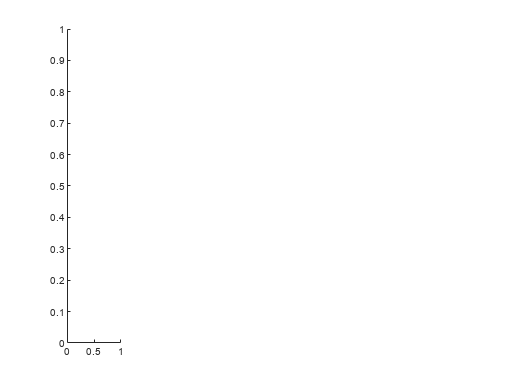

mBase = zeros(6,1);
qBase = zeros(6,2);
mPost = zeros(6,1);
qPost = zeros(6,2);
pVal = zeros(6,1);
zVal = zeros(6,1);
srVal = zeros(6,1);

figure
t = tiledlayout(1,6);
nexttile

varControl = rmoutliers(control.bfi,"quartiles");

Unable to resolve the name 'control.bfi'.

varExenatide = rmoutliers(exenatide.bfi,"quartiles");
x = [varControl;varExenatide];
g1 = repmat({'Control'},length(varControl),1);
g2 = repmat({'Exenatide'},length(varExenatide),1);
g = [g1;g2];
boxplot(x,g,'Notch','on','Symbol','','Colors','kr')
H=sigstar([1,2],pBfi);
title('BFI')
ylabel('BFI [a.u]')
pbaspect([1 2 1])
mBase(1) = median(varControl);
qBase(1,:) = quantile(varControl,[0.25 0.75]);
mPost(1) = median(varExenatide);
qPost(1,:) = quantile(varExenatide,[0.25 0.75]);
pVal(1) = pBfi;
zVal(1) = statBfi.zval;
srVal(1) = statBfi.signedrank;

nexttile
varControl = rmoutliers(control.sigma,"quartiles");
varExenatide = rmoutliers(exenatide.sigma,"quartiles");
x = [varControl;varExenatide];
g1 = repmat({'Control'},length(varControl),1);
g2 = repmat({'Exenatide'},length(varExenatide),1);
g = [g1;g2];
boxplot(x,g,'Notch','on','Symbol','','Colors','kr')
H=sigstar([1,2],pSigma);
title('Sigma')
ylabel('Sigma [a.u]')
pbaspect([1 2 1])
mBase(2) = median(varControl);
qBase(2,:) = quantile(varControl,[0.25 0.75]);
mPost(2) = median(varExenatide);
qPost(2,:) = quantile(varExenatide,[0.25 0.75]);
pVal(2) = pSigma;
zVal(2) = statSigma.zval;
srVal(2) = statSigma.signedrank;

nexttile
varControl = rmoutliers(control.aucPass,"quartiles");
varExenatide = rmoutliers(exenatide.aucPass,"quartiles");
x = [varControl;varExenatide];
g1 = repmat({'Control'},length(varControl),1);
g2 = repmat({'Exenatide'},length(varExenatide),1);
g = [g1;g2];
boxplot(x,g,'Notch','on','Symbol','','Colors','kr')
H=sigstar([1,2],pAucPass);
title('AUC')
ylabel('AUC [a.u]')
pbaspect([1 2 1])
mBase(3) = median(varControl);
qBase(3,:) = quantile(varControl,[0.25 0.75]);
mPost(3) = median(varExenatide);
qPost(3,:) = quantile(varExenatide,[0.25 0.75]);
pVal(3) = pAucPass;
zVal(3) = statAucPass.zval;
srVal(3) = statAucPass.signedrank;


nexttile
varControl = rmoutliers(control.SNRauc,"quartiles");
varExenatide = rmoutliers(exenatide.SNRauc,"quartiles");
x = [varControl;varExenatide];
g1 = repmat({'Control'},length(varControl),1);
g2 = repmat({'Exenatide'},length(varExenatide),1);
g = [g1;g2];
boxplot(x,g,'Notch','on','Symbol','','Colors','kr')
H=sigstar([1,2],pSNRauc);
title('SNR')
ylabel('SNR [a.u]')
pbaspect([1 2 1])
mBase(4) = median(varControl);
qBase(4,:) = quantile(varControl,[0.25 0.75]);
mPost(4) = median(varExenatide);
qPost(4,:) = quantile(varExenatide,[0.25 0.75]);
pVal(4) = pSNRauc;
zVal(4) = statSNRauc.zval;
srVal(4) = statSNRauc.signedrank;

nexttile
varControl = rmoutliers(control.locs,"quartiles");
varExenatide = rmoutliers(exenatide.locs,"quartiles");
x = [varControl;varExenatide];
g1 = repmat({'Control'},length(varControl),1);
g2 = repmat({'Exenatide'},length(varExenatide),1);
g = [g1;g2];
boxplot(x,g,'Notch','on','Symbol','','Colors','kr')
H=sigstar([1,2],pLocs);
title('Frequency')
ylabel('Frequency [Hz]')
pbaspect([1 2 1])
mBase(5) = median(varControl);
qBase(5,:) = quantile(varControl,[0.25 0.75]);
mPost(5) = median(varExenatide);
qPost(5,:) = quantile(varExenatide,[0.25 0.75]);
pVal(5) = pLocs;
zVal(5) = statLocs.zval;
srVal(5) = statLocs.signedrank;

nexttile
varControl = rmoutliers(control.p,"quartiles");
varExenatide = rmoutliers(exenatide.p,"quartiles");
x = [varControl;varExenatide];
g1 = repmat({'Control'},length(varControl),1);
g2 = repmat({'Exenatide'},length(varExenatide),1);
g = [g1;g2];
boxplot(x,g,'Notch','on','Symbol','','Colors','kr')
H=sigstar([1,2],pP);
title('Prominence')
ylabel('Prominence [a.u]')
pbaspect([1 2 1])
mBase(6) = median(varControl);
qBase(6,:) = quantile(varControl,[0.25 0.75]);
mPost(6) = median(varExenatide);
qPost(6,:) = quantile(varExenatide,[0.25 0.75]);
pVal(6) = pP;
zVal(6) = statP.zval;
srVal(6) = statP.signedrank;

t.TileSpacing = 'compact';
t.Padding = 'compact';

statT = table(mBase,qBase,mPost,qPost,pVal,zVal,srVal)

## Distance vs. pearson correlation plot

fNames{1} ='Norm1HighBase_reg_segmented.mat'; 
fNames{2} ='Norm2HighBase_reg_segmented.mat'; 
fNames{3} ='Norm3HighBase_reg_segmented.mat'; 
fNames{4} ='Norm4HighBase_reg_segmented.mat'; 
fNames{5} ='Norm5HighBase_reg_segmented.mat'; 
fNames{6} ='Norm6HighBase_reg_segmented.mat'; 
fNames{7} ='Norm7HighBase_reg_segmented.mat'; 
fNames{8} ='Norm9HighBase_reg_segmented.mat'; 
fNames{9} ='Norm10HighBase_reg_segmented.mat';
Fs = 1;
SDcorrelation = [];
SDdistance = [];
for i = 1:length(fNames)
    load(fNames{i});
    
    numves = length(result.segmves);
    sig1 = result.segmves(1).tsPass;
    coord1 = result.segmves(1).rprops.Centroid;
    
    corrVal = zeros(numves,1);
    distVal = zeros(numves,1);
    
    for ii = 1:numves
        [R,P] = corrcoef(sig1,result.segmves(ii).tsPass);
        corrVal(ii) = R(2);
        coord2= result.segmves(ii).rprops.Centroid;
        x = [coord1;coord2];
        distVal(ii) = pdist(x,'euclidean');
    end 
    SDcorrelation = [SDcorrelation;corrVal];
    SDdistance = [SDdistance;distVal];
end 

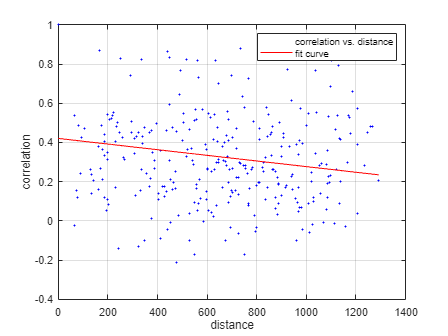


% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( SDdistance, SDcorrelation );

% Set up fittype and options.
ft = fittype( 'poly1' );
opts = fitoptions( 'Method', 'LinearLeastSquares');

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'linear regression' );
h = plot( fitresult, xData, yData );
legend( h, 'correlation vs. distance', 'fit curve', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'distance', 'Interpreter', 'none' );
ylabel( 'correlation', 'Interpreter', 'none' );
grid on

fitresult 

fitresult =      Linear model Poly1:
     fitresult(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =  -0.0001438  (-0.0002282, -5.936e-05)
       p2 =      0.4202  (0.3595, 0.481)

gof 

gof = struct with fields:
           sse: 18.6545
       rsquare: 0.0348
           dfe: 311
    adjrsquare: 0.0317
          rmse: 0.2449


## k-means hierarchal clustering tree

load SHR1HighBase_reg_segmented.mat
%clusters and frequnecy
numves = length(result.segmves);
sig1 = result.segmves(1).tsPass;
coord1 = result.segmves(1).rprops.Centroid;
tmp1 = result.segmves(1).tmpPass;

corrVal = zeros(numves,1);
distVal = zeros(numves,1);
tmpVal = zeros(numves,1);
    
for ii = 1:numves
    % calculate correlation coeff 
    [R,P] = corrcoef(sig1,result.segmves(ii).tsPass);
    corrVal(ii) = R(2);

    % calculate distance 
    coord2= result.segmves(ii).rprops.Centroid;
    x = [coord1;coord2];
    distVal(ii) = pdist(x,'euclidean');
    
    % calculate correlation coeff 
    [R,P] = corrcoef(tmp1,result.segmves(ii).tmpPass);
    tmpVal(ii) = R(2);
end 
%meas = [corrVal,distVal,tmpVal];
meas = distVal;
eucD = pdist(meas,'euclidean');
clustTreeEuc = linkage(eucD,'average');
cophenet(clustTreeEuc,eucD)

ans = 0.7303

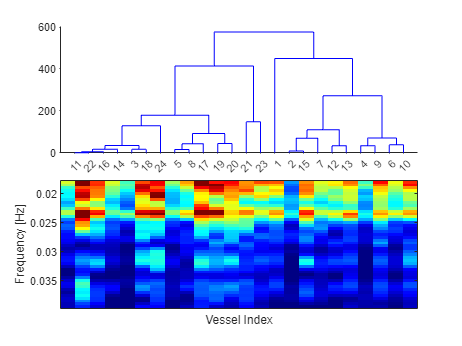

ans = 0.7303

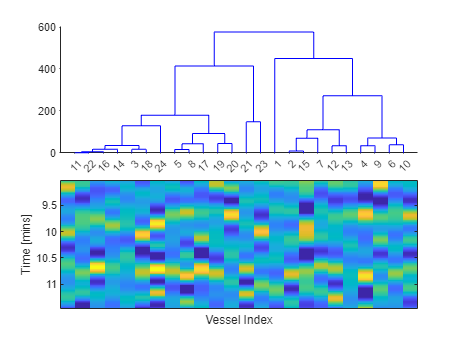

figure
tiledlayout(2,1,'TileSpacing','compact')
nexttile
[h,nodes] = dendrogram(clustTreeEuc,0);
h_gca = gca;
h_gca.TickDir = 'out';
h_gca.TickLength = [.002 0];

vesOrd = str2num(h_gca.XTickLabel);
%t = linspace(1,length(result.segmves(1).tsPass)/60,length(result.segmves(1).tsPass));
t = result.fois;
%tsMatOrdered = cell2mat({result.segmves.tsPass}.');
tsMatOrdered = [result.segmves.tmpNoisy]';
tsMat = zeros(numves,length(t));
for i = 1:length(vesOrd)
    idx = vesOrd(i);
    tsMat(i,:) = tsMatOrdered(idx,:);
end 
% cut out fois 
range = (t>0.018 & t<0.04);
t = t(range);
tsMatNew = zeros(size(tsMat,1),sum(range));
for i = 1:size(tsMat,1)
    tsi = tsMat(i,:);
    tsMatNew(i,:) = tsi(range);
end 
tsMat = tsMatNew;

nexttile
imagesc(tsMat,'XData',t)
clim([prctile(tsMat,5,'all'),prctile(tsMat,99,'all')])
set(gca, 'ydir', 'normal');
xlabel('Frequency [Hz]')
ylabel('Vessel Index')
ax = gca;
ax.YTickLabel = [];
ax.YTick = [];
colormap jet
view([90 90])

## LZ frequency map 

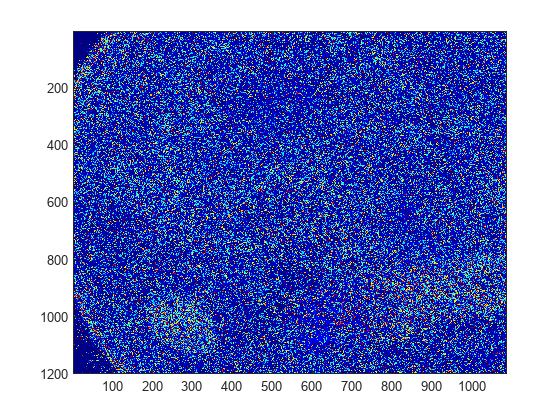

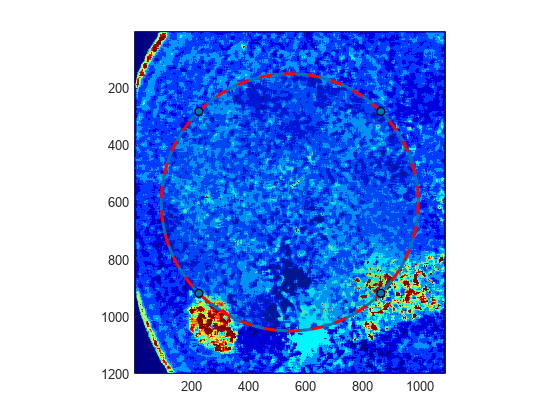

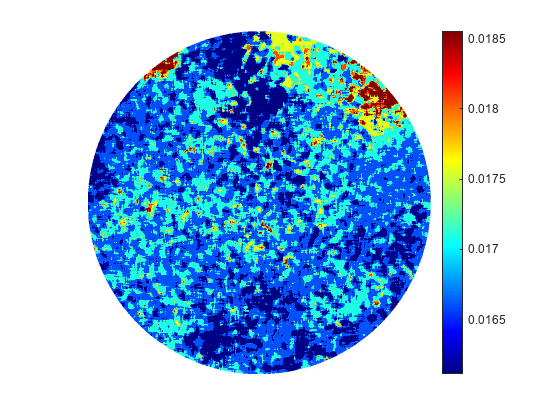

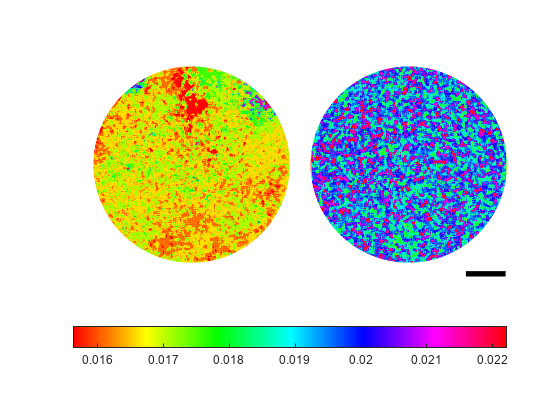


addpath("F:\lzContrastData");

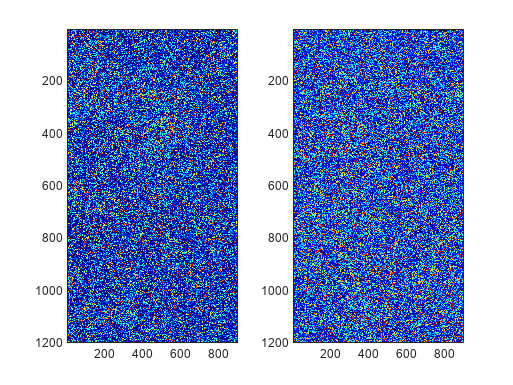

load('Norm2LowBase.mat')
dataLSCI = 1./dataLSCI.^2;
Fs = 1;                           
T = 1/Fs;               
L = size(dataLSCI,3);            
t = (0:L-1)*T;      
n = 2^nextpow2(L);

Y = fft(dataLSCI,n,3);
f = Fs*(0:(n/2))/n;
P2 = abs(Y/L);
P1 = P2(:,:,1:n/2+1);
P1(:,:,2:end-1) = 2*P1(:,:,2:end-1);
fRange = [0.015 0.04];
fois = f(f>fRange(1) & f<fRange(2));
spec = P1(:,:,(f>fRange(1) & f<fRange(2)));

[pows,I] = max(spec,[],3,'omitnan');
fMap = fois(I);
I = imagesc(fMap);
clim([prctile(fMap,5,'all') prctile(fMap,99,'all')])
A = fMap; 
fun = @(x) median(x(:));
B1 = nlfilter(A,[15 15],fun); 

clearvars dataLSCI

addpath("G:\lzContrastData");
load('SHR1LowBase.mat')
dataLSCI = 1./dataLSCI.^2;
Fs = 1;                           
T = 1/Fs;               
L = size(dataLSCI,3);            
t = (0:L-1)*T;      
n = 2^nextpow2(L);

Y = fft(dataLSCI,n,3);
f = Fs*(0:(n/2))/n;
P2 = abs(Y/L);
P1 = P2(:,:,1:n/2+1);
P1(:,:,2:end-1) = 2*P1(:,:,2:end-1);
fRange = [0.015 0.04];
fois = f(f>fRange(1) & f<fRange(2));
spec = P1(:,:,(f>fRange(1) & f<fRange(2)));

[pows,I] = max(spec,[],3,'omitnan');
fMap = fois(I);
I = imagesc(fMap);
clim([prctile(fMap,5,'all') prctile(fMap,99,'all')])
A = fMap; 

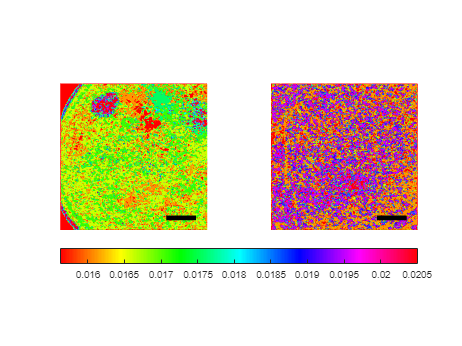

fun = @(x) median(x(:));
B2 = nlfilter(A,[15 15],fun); 

both = [B1 B2];
figure
t = tiledlayout(1,2);
nexttile;
s = pcolor(B1(:,1:900));
colormap hsv
clim([prctile(both,5,'all') prctile(both,99,'all')])
s.EdgeColor = 'none';
s.FaceColor = 'interp';
ax = gca;
set(ax, 'Visible','off');
pbaspect([1 1 1]);
barLen= 1000; %desired length in microns 
pixLen= barLen/sizePix; % length in pixels 
x = 650;
y= 100;
hold on 
plot([x; x+pixLen],[y; y],'-k', 'LineWidth', 4)
hold off 

nexttile;
s = pcolor(B2);
colormap hsv
clim([prctile(both,5,'all') prctile(both,99,'all')])
s.EdgeColor = 'none';
s.FaceColor = 'interp';
ax = gca;
set(ax, 'Visible','off');
pbaspect([1 1 1]);
sizePix=5.5; %in microns 
barLen= 1000; %desired length in microns 
pixLen= barLen/sizePix; % length in pixels 
x = 650;
y= 100;
hold on 
plot([x; x+pixLen],[y; y],'-k', 'LineWidth', 4)
hold off 

cb = colorbar;
cb.Layout.Tile = 'south';


## distance vs cross correlation calculation

fNames{1} ='Norm1HighBase_reg_segmented.mat'; 
fNames{2} ='Norm2HighBase_reg_segmented.mat'; 
fNames{3} ='Norm3HighBase_reg_segmented.mat'; 
fNames{4} ='Norm4HighBase_reg_segmented.mat'; 
fNames{5} ='Norm5HighBase_reg_segmented.mat'; 
fNames{6} ='Norm6HighBase_reg_segmented.mat'; 
fNames{7} ='Norm7HighBase_reg_segmented.mat'; 
fNames{8} ='Norm9HighBase_reg_segmented.mat'; 
fNames{9} ='Norm10HighBase_reg_segmented.mat';

cfsAll = [];
distAll = [];

for f = 1:length(fNames)
    f
    load(fNames{f})
    tsPass = normalize(double(cell2mat({result.segmves.tsPass}.'))');
    numVes = size(tsPass,2);
    pairs = nchoosek(1:numVes,2);
    numPairs = size(pairs,1);
    cfsMax = size(numPairs,1);
    distances = zeros(numPairs,1);

    for i = 1:numPairs 
        % compute vessel distance 
        coord1 = result.segmves(pairs(i,1)).rprops.Centroid;
        coord2 = result.segmves(pairs(i,2)).rprops.Centroid;
        x = [coord1;coord2];
        distances(i) = pdist(x,'euclidean');
    
        % compute max cross correlation 
        ts1 = tsPass(:,pairs(i,1));
        ts2 = tsPass(:,pairs(i,2));
        [xcf,~] = xcorr(ts1,ts2,0,'normalized');
        [M,I] = max(xcf);
        cfsMax(i) = M;
    end 
    cfsAll = [cfsAll;cfsMax'];
    distAll = [distAll;distances];
end 

% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( distAll, cfsAll );

% Set up fittype and options.
ft = fittype( 'poly1' );
opts = fitoptions( 'Method', 'LinearLeastSquares');

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
f1 = figure( 'Name', 'linear regression' );
h = plot( fitresult, xData, yData );
legend( h, 'correlation vs. distance', 'fit curve', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'distance', 'Interpreter', 'none' );
ylabel( 'correlation', 'Interpreter', 'none' );
xlim([0 1400]);
ylim([-0.5 1])
fitresult 
gof 


fNames{1} = 'Norm1HighPost_reg_segmented.mat'; 
fNames{2} ='Norm2HighPost_reg_segmented.mat'; 
fNames{3} ='Norm3HighPost_reg_segmented.mat'; 
fNames{4} ='Norm4HighPost_reg_segmented.mat'; 
fNames{5} ='Norm5HighPost_reg_segmented.mat'; 
fNames{6} ='Norm6HighPost_reg_segmented.mat'; 
fNames{7} ='Norm7HighPost_reg_segmented.mat'; 
fNames{8} ='Norm9HighPost_reg_segmented.mat'; 
fNames{9} ='Norm10HighPost_reg_segmented.mat';

cfsAll = [];
distAll = [];

for f = 1:length(fNames)
    f
    load(fNames{f})
    tsPass = normalize(double(cell2mat({result.segmves.tsPass}.'))');
    numVes = size(tsPass,2);
    pairs = nchoosek(1:numVes,2);
    numPairs = size(pairs,1);
    cfsMax = size(numPairs,1);
    distances = zeros(numPairs,1);

    for i = 1:numPairs 
        % compute vessel distance 
        coord1 = result.segmves(pairs(i,1)).rprops.Centroid;
        coord2 = result.segmves(pairs(i,2)).rprops.Centroid;
        x = [coord1;coord2];
        distances(i) = pdist(x,'euclidean');
    
        % compute max cross correlation 
        ts1 = tsPass(:,pairs(i,1));
        ts2 = tsPass(:,pairs(i,2));
        [xcf,~] = xcorr(ts1,ts2,0,'normalized');
        [M,I] = max(xcf);
        cfsMax(i) = M;
    end 
    cfsAll = [cfsAll;cfsMax'];
    distAll = [distAll;distances];
end 

% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( distAll, cfsAll );

% Set up fittype and options.
ft = fittype( 'poly1' );
opts = fitoptions( 'Method', 'LinearLeastSquares');

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
f2 = figure( 'Name', 'linear regression' );
h = plot( fitresult, xData, yData );
legend( h, 'correlation vs. distance', 'fit curve', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'distance', 'Interpreter', 'none' );
ylabel( 'correlation', 'Interpreter', 'none' );
xlim([0 1400]);
ylim([-0.5 1])
fitresult 
gof 


fNames{1} ='SHR1HighBase_reg_segmented.mat'; 
fNames{2} ='SHR2HighBase_reg_segmented.mat'; 
fNames{3} ='SHR3HighBase_reg_segmented.mat'; 
fNames{4} ='SHR4HighBase_reg_segmented.mat'; 
fNames{5} ='SHR5HighBase_reg_segmented.mat'; 
fNames{6} ='SHR6HighBase_reg_segmented.mat'; 
fNames{7} ='SHR7HighBase_reg_segmented.mat'; 
fNames{8} ='SHR8HighBase_reg_segmented.mat'; 
fNames{9} ='SHR9HighBase_reg_segmented.mat';

cfsAll = [];
distAll = [];

for f = 1:length(fNames)
    f
    load(fNames{f})
    tsPass = normalize(double(cell2mat({result.segmves.tsPass}.'))');
    numVes = size(tsPass,2);
    pairs = nchoosek(1:numVes,2);
    numPairs = size(pairs,1);
    cfsMax = size(numPairs,1);
    distances = zeros(numPairs,1);

    for i = 1:numPairs 
        % compute vessel distance 
        coord1 = result.segmves(pairs(i,1)).rprops.Centroid;
        coord2 = result.segmves(pairs(i,2)).rprops.Centroid;
        x = [coord1;coord2];
        distances(i) = pdist(x,'euclidean');
    
        % compute max cross correlation 
        ts1 = tsPass(:,pairs(i,1));
        ts2 = tsPass(:,pairs(i,2));
        [xcf,~] = xcorr(ts1,ts2,0,'normalized');
        [M,I] = max(xcf);
        cfsMax(i) = M;
    end 
    cfsAll = [cfsAll;cfsMax'];
    distAll = [distAll;distances];
end 

% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( distAll, cfsAll );

% Set up fittype and options.
ft = fittype( 'poly1' );
opts = fitoptions( 'Method', 'LinearLeastSquares');

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
f3= figure( 'Name', 'linear regression' );
h = plot( fitresult, xData, yData );
legend( h, 'correlation vs. distance', 'fit curve', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'distance', 'Interpreter', 'none' );
ylabel( 'correlation', 'Interpreter', 'none' );
xlim([0 1400]);
ylim([-0.5 1])
fitresult 
gof 


fNames{1} = 'SHR1HighPost_reg_segmented.mat'; 
fNames{2} ='SHR2HighPost_reg_segmented.mat'; 
fNames{3} ='SHR3HighPost_reg_segmented.mat'; 
fNames{4} ='SHR4HighPost_reg_segmented.mat'; 
fNames{5} ='SHR5HighPost_reg_segmented.mat'; 
fNames{6} ='SHR6HighPost_reg_segmented.mat'; 
fNames{7} ='SHR7HighPost_reg_segmented.mat'; 
fNames{8} ='SHR8HighPost_reg_segmented.mat'; 
fNames{9} ='SHR9HighPost_reg_segmented.mat';

cfsAll = [];
distAll = [];

for f = 1:length(fNames)
    f
    load(fNames{f})
    tsPass = normalize(double(cell2mat({result.segmves.tsPass}.'))');
    numVes = size(tsPass,2);
    pairs = nchoosek(1:numVes,2);
    numPairs = size(pairs,1);
    cfsMax = size(numPairs,1);
    distances = zeros(numPairs,1);

    for i = 1:numPairs 
        % compute vessel distance 
        coord1 = result.segmves(pairs(i,1)).rprops.Centroid;
        coord2 = result.segmves(pairs(i,2)).rprops.Centroid;
        x = [coord1;coord2];
        distances(i) = pdist(x,'euclidean');
    
        % compute max cross correlation 
        ts1 = tsPass(:,pairs(i,1));
        ts2 = tsPass(:,pairs(i,2));
        [xcf,~] = xcorr(ts1,ts2,0,'normalized');
        [M,I] = max(xcf);
        cfsMax(i) = M;
    end 
    cfsAll = [cfsAll;cfsMax'];
    distAll = [distAll;distances];
end 

% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( distAll, cfsAll );

% Set up fittype and options.
ft = fittype( 'poly1' );
opts = fitoptions( 'Method', 'LinearLeastSquares');

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
f4 = figure( 'Name', 'linear regression' );
h = plot( fitresult, xData, yData );
legend( h, 'correlation vs. distance', 'fit curve', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'distance', 'Interpreter', 'none' );
ylabel( 'correlation', 'Interpreter', 'none' );
xlim([0 1400]);
ylim([-0.5 1])
fitresult 
gof 